# Exploring Vectors and Matrices

## Introduction

So far, we have explored variables, functions, symbolic expressions and loops (amongst other concepts!) in MATLAB. Many programming languages are equally as effective as MATLAB is at using all these things, but what sets MATLAB apart is its fantastically optimised inbuilt ability to handle vectors and matrices. After all, MATLAB stands for **mat**rix **lab**oratories!

Today, we aim to teach you the basics of defining and using vectors and matrices, as well as their associated operations in MATLAB. In addition, we will provide some examples of solving vector problems using these operations. 

In the following sections, you will learn how to:

- Create and index vectors and matrices

- Use common vector and matrix operations (such as [`zeros`](https://au.mathworks.com/help/matlab/ref/zeros.html), [`ones`](https://au.mathworks.com/help/matlab/ref/ones.html), [`eye`](https://au.mathworks.com/help/matlab/ref/eye.html), [`dot`](https://au.mathworks.com/help/matlab/ref/dot.html), [`cross`](https://au.mathworks.com/help/matlab/ref/cross.html) and [`norm`](https://au.mathworks.com/help/matlab/ref/norm.html)) 

- Find angles and projections between vectors and solve vector equations.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

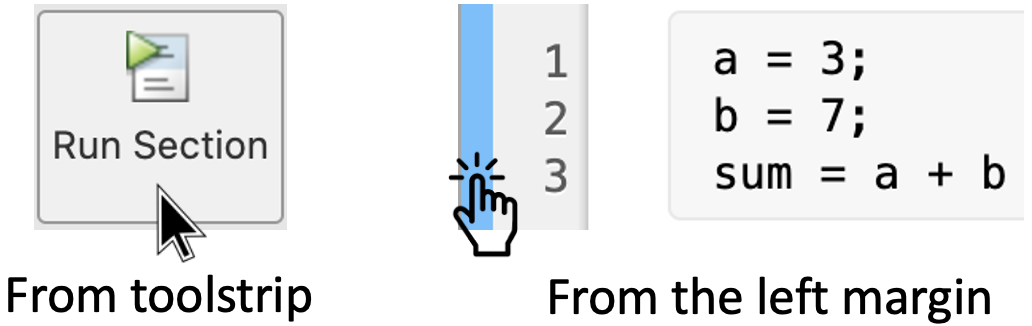

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Creating and Using Vectors and Matrices (Revision)

We start by looking at how we create vectors and matrices in MATLAB. Most of this is a recap of the Functions workshop, so it will be kept brief.

### **1.1 Creating vectors**

#### **Directly writing the vector**

One option is to simply write out the vector. To do this, we use **square braces**, "`[]`", to define the boundaries of our vector. Below, we create a vector from 1 to 5 using this method:

[1,2,3,4,5] 

To create a **column vector**, we use **semicolons**, "`;`", as follows:

[1;2;3;4;5] % semicolons create new rows

This option is good for making small vectors of easy-to-write values. Obviously, it's more tricky if we'd like to create, e.g., a large vector of mostly irrational numbers.

#### The colon operator

Another option is to use the [colon operator "`:`"](https://au.mathworks.com/help/matlab/ref/colon.html). If we wanted to create a row vector starting at 1 and ending at 10, increasing by increments of 1, we can do the following:

1:10  % notice that this is the same vector!

We can also create a row vector which increments up by different amounts:

1.5:0.1:2 % we can increment by any value

We can create a row vector from 2 to 1.5, decrementing by 0.1, as follows:

2:-0.1:1.5 % a negative middle number decrements

Finally, If we set the last number such that we can't reach it using our increment, notice that MATLAB will not end on that final number (but stop just short of it):

2.7:0.1:pi % we stop here at 3.1, not 3.1416...

The colon operator is good when we need a specific spacing between successive elements in our vector.

#### `Using linspace` 

Sometimes, however, we don't care about the size of our spacing, but simply want a linearly spaced vector between two defined endpoints. We can use [`linspace`](https://au.mathworks.com/help/matlab/ref/linspace.html) to achieve this.

Let's create a linearly spaced vector from 0 to 2*pi, with 10 elements in our vector. We achieve this as follows:

linspace(0,2*pi,10) % linearly spaced vector with 10 elements

`linspace` is particularly useful when defining a vector over irrational numbers. 

#### Creating vectors using vectors

We can also create vectors using vectors. To demonstrate this, we will create a vector of sine values from `x = 0 `to `x = 2*pi`, as follows:

X = linspace(0,2*pi,100);
Y = sin(X); % notice this creates a vector!
plot(X,Y)

The plot should hopefully convince you that we've created a vector of sine values! You can also check these values in the command window to see that `sineVec `is indeed a vector. You would have seen vectors being created from vectors repeatedly in the Functions workshop.

### 1.2 Creating matrices

Creating matrices is similar to creating vectors. You could think of it as 'stacking' a bunch of vectors into a 2D shape. Since we will only deal with small matrices, we will focus on directly writing them (although the above techniques for vectors can be used to create matrices also).

We can directly write a matrix of values as follows:

[1,2,3;4,5,6;7,8,9] % this creates a 3x3 matrix

As you can see, we have effectively made 3 row vectors, which we separate by a semicolon (to indicate a new line in our matrix). We could also write a matrix using predefined vectors, as follows:

vec1 = [1,2,3];
vec2 = [4,5,6];
vec3 = [7,8,9];
[vec1;vec2;vec3] % notice this is the same as the above matrix

Play around with writing your own matrices!

### 1.3 Indexing Vectors and Matrices

We often want to access the values in our vectors and matrices. To do that, we can **index **them.

The basic idea is that MATLAB starts indexing the elements of a vector from 1, and increases sequentially left-to-right. It's quite simple in practice:

vec = [1,2,3];
vec(1) % this is the first element of vec
vec(2) % this is the second 
vec(3) % this is the third 

We sometimes don't know how long a vector is. We can use `end` to index the last element in such instances:

vec(end) % gives us the last element
vec(end-1) % we can even look at the second last element!

Finally, if we wish to index the whole vector, we can simply use "`:`", as follows:

vec(:) % this indexes the whole vector

Similar rules apply to matrices, however we index via the **row **and **column **numbers. For example, in a `3x3 `matrix, we might wish to access the value in row 2, column 2. To do so, we would write:

M = [1,2,3;4,5,6;7,8,9]; % define a matrix M 
M(2,2) % indexes the middle element of this 3x3 matrix

We could index, eg, the first row of `M` as follows:

M(1,:) % gives us all the values in row 1 of M

**Question:** Can you think of how to index the **third-last** **column **of a matrix, if you didn't know it's dimensions?

## 2. Common Vector and Matrix Operations

You've undoubtedly come across multiple vector and matrix operations, either in your prior studies or in this course. A lot of these are in-built functions in MATLAB. We will provide a brief list of them, alongside some examples. First, let's define some vectors; here, the entries represent the *i, j *and *k *coordinates, respectively:

u = [1,2,3];
v = [2,4,6];
w = [1,-5,3];

 To take the norm of a vector, we use [`norm`](https://www.mathworks.com/help/matlab/ref/norm.html):

norm(u) % = sqrt(u(1)^2+u(2)^2+u(3)^2)

To take the dot product between vectors, we use [`dot`](https://www.mathworks.com/help/matlab/ref/dot.html):

dot(u,v) % notice this requires 2 arguments!

and to take the cross product between vectors, we use [`cross`](https://www.mathworks.com/help/matlab/ref/cross.html):

cross(u,w) % again, notice 2 arguments

Sometimes, you may wish to create vectors or matrices whose entries are all ones or zeros. To do this in MATLAB, you can use the functions [`ones`](https://www.mathworks.com/help/matlab/ref/ones.html) and [`zeros`](https://www.mathworks.com/help/matlab/ref/zeros.html). See if you can determine how these functions are working below:

ones(5,1)
zeros(1,5)
ones(3)
zeros(2)

Finally, we may wish to create an identity matrix for some $n \times n$ matrix. To do this, we use the function [`eye`](https://www.mathworks.com/help/matlab/ref/eye.html), as below:

eye(3)

There are many, *many*, ***many***, ***many*** more built-in functions for vectors and matrices---far more than we can list here. So, if you wish, you can explore around the MATLAB documentation to find some of the crazier ones. A personal favourite is the [`magic`](https://www.mathworks.com/help/matlab/ref/magic.html) matrix (maybe you could find a use for this one in your own studies?).

## 3. Using Operations to Solve Questions

Now that we've outlined some common functions, let's use them to solve some questions. 

As an example, let's see if vectors `u` and `w` are orthogonal using the dot product:

%redefining u, v and w here
u = [1,2,3];
v = [2,4,6];
w = [1,-5,3];
dot(u,w) % this should equal 0 for orthogonal vectors

Let's then check if `u` and `v` are parallel using the cross product:

cross(u,v) % this should equal the 0 vector for parallel vectors

Next, let's define a vector `x` and find the angle between it and the vector `u`. We will do this using the cross product, but later you will be asked to do so using the dot product:

x = [4,3,2];
asind( norm(cross(x,u))/(norm(x)*norm(u)) ) % angle in degrees

Note that here, [`asind`](https://www.mathworks.com/help/matlab/ref/asind.html) is MATLAB's inverse sine function, and it returns degrees (not radians like [`asin`](https://www.mathworks.com/help/matlab/ref/asin.html) does). 

**Question**: Can you see how we can derive the above expression for the angle? **Hint**: Consider the geometrical definition of the cross product!

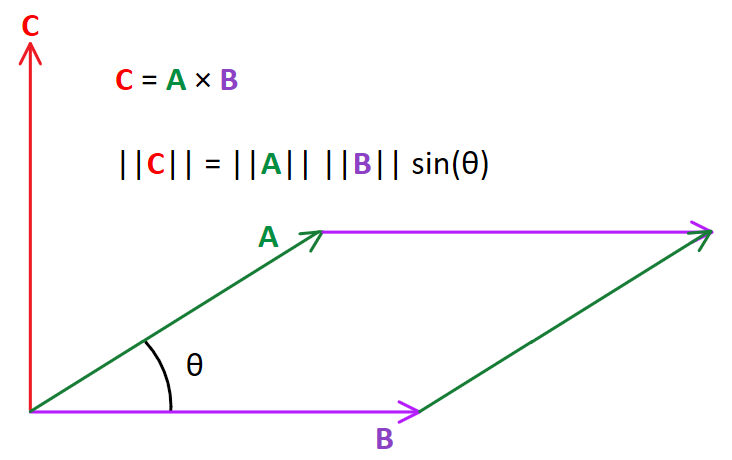

We can also combine the operations mentioned above to find the projection of a vector (let's use some 2d vectors, `x` and `y`), as follows:

x = [-1,5];
y = [3,6];
proj = dot(x,y)/(norm(y)^2)*y

Let's plot these 3 vectors (`proj,` `x` and `y`). Don't worry too much about the code here; it isn't important you understand how it's all working, just that you understand the output.

plot([0,x(1)],[0,x(2)],'b',[0,y(1)],[0,y(2)],'g',...
    [0,proj(1)],[0,proj(2)],'k--',[proj(1),x(1)],[proj(2),x(2)],':','linewidth',1.5)
legend('x','y','proj','normal to y','location','best')
grid on
axis equal
xlabel('x coordinate')
ylabel('y coordinate')
title('Projection vector of x onto y')

Can you see why the `proj` vector is the projection of `x` onto y? Consider a light source propagating at an angle orthogonal to the `y `vector, shining onto `x`; the projection is then the "shade" that `x` casts on `y`.

Finally, let's solve a simple vector problem. This will require using [syms](https://www.mathworks.com/help/symbolic/syms.html) (you should hopefully remember this from the earlier workshops!). Let's say we had vectors `a` and `b`, as follows:

syms c
a = [2,-1,1];
b = [1,c,2];

 Let us find the values `c` such that the angle between vectors `a` and `b` is `pi/3` radians. In that situation, we would expect `pi/3` to be equal to:

angle = acos(dot(a,b)/(norm(a)*norm(b))) == pi/3

This produces a symbolic expression for the angle. Since we know this should equal `pi/3`, we can then solve for `c` as follows (think about why this works; if you're struggling to understand this, feel free to ask the tutors for help):

solve(angle) % these are the values of c that give an angle of pi/3

Therefore, in this problem, `c` is equal to -17 or 1. Check if these values are correct!

As you can see, we can use MATLAB to compute and solve several tedious or difficult problems involving vectors.

## 4. Hands on practice

### Activity 1:

For the two vectors below, calculate the cross product, the norms and the unit vectors in the same direction. Then calculate the angle between the two vectors using cross product.    

x1 = [4,-5,5]
y1 = [3,-4,-1]

Write you code here:

### Activity 2:

Determine which pairs of vectors are perpendicular. If they are not perpendicular, find the angle between them using the dot product.  Remember that


$$u\cdot v = \|u\| \|v\| \cos (\theta)$$


u1 = [2, 2,3]
v1 = [-3,-6,6]
w1 = [-8,-2.5,7]

Write your code here:

### **Activity 3: (optional)**

For two vectors of your choice that are not parallel and not orthogonal, calculate the cross product.  Verify that the result is orthogonal using the dot product.

Write your code here:

### Activity 4: (optional)

A ship is currently at the island Gusto Sphreez.  The ship needs to travel from Gusto Sphreez to a port on the island Gusto Pilica.  The captain of the ship knows of the legendary Blue-Eyes White Dragon Reef nearby and he would like to avoid it.  He only has an approximate location for the reef, and he knows that if the difference between the bearings of the reef and the port is less than about 5 degrees, then there is a danger of wrecking the ship and so the direct route would not be safe to use.  

Using the relative coordinates, plot the vectors and determine whether the direct route is safe or not.  (Hint: it may be useful to find the angle an arbitrary vector pointing in the x-axis to each location after plotting.)

GustoS = [0,0]
GustoP  = [5750,5000]
BEWDR = [3590,3725]

Write your code here:

### Activity 5 - Application of dot product: (optional)

A surface normal is a vector that is at a right angle to a surface.  Suppose we have a light source in the sky, such as the sun.  In computer graphics, a basic lighting algorithm is to say that the intensity of an incoming light is proportional to the cosine of the angle between the direction of the light (${\mathit{\mathbf{P}}}_{\mathit{\mathbf{L}}}$) and the surface normal ($\mathit{\mathbf{n}}$) at some point observation point $\mathit{\mathbf{P}}$.  To calculate the intensity of incoming light at point $\mathit{\mathbf{P}}$, we can use the equations, 


$$\omega ={\mathit{\mathbf{P}}}_{\mathit{\mathbf{L}}} -\mathit{\mathbf{P}}$$



$$\text{Intensity} = \max(0, \textbf{n}\cdot \hat{\omega})$$


If we have a light source at $P_L$ = [50,50,100]  and $\mathit{\mathbf{P}}$ = [2,3,1], calculate the intensity of the incoming light.  (Remember that the unit vector  $\hat{\textbf{x}} = \textbf{x}  /  ||\textbf{x}||$, and so **n **would be given by  $n = \textbf{P} / ||\textbf{P}||$)

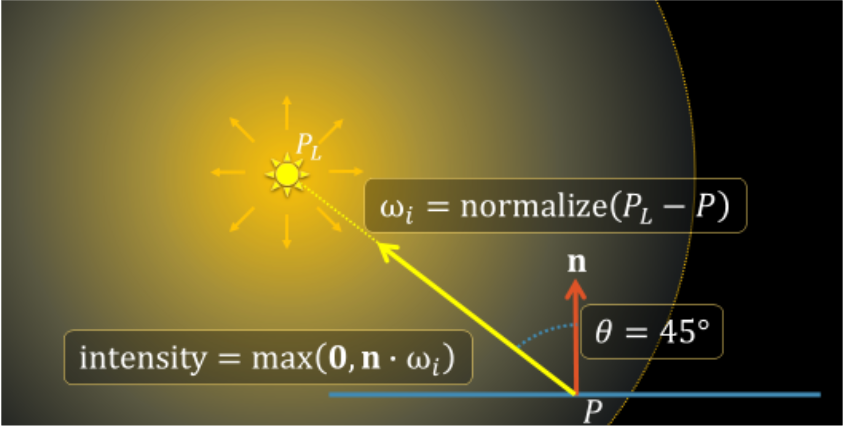

PL = [50,50,100]
P = [2,3,1]

Write your code here:

We can interpret the results geometrically. If the light source was directly above the point $\mathit{\mathbf{P}}$, that is ${\mathit{\mathbf{P}}}_L =\textrm{kP}$ for some positive constant k we obtain a value of 1. What does this mean? Why would we want to take the max of 0 and the dot product?